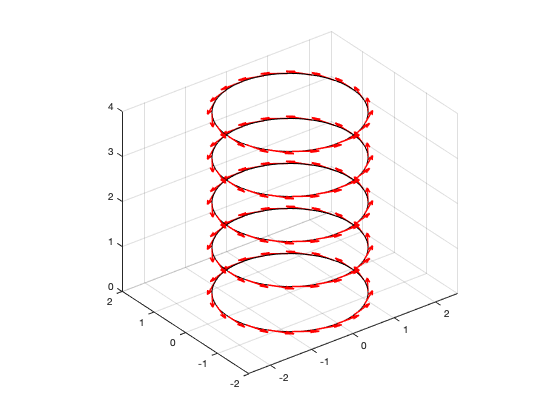

%% PASO 1: CARACTERÍSTICAS DE LA ESPIRA
nL = 5;          % Número de espiras
N = 20;          % Puntos por espira
R = 1.5;         % Radio de cada espira (m)
sz = 1;          % Separación entre espiras (paso en Z, m)
I = 300;         % Corriente (A)
mu0 = 4*pi*1e-7; % Permeabilidad magnética del vacío
km = mu0 * I / (4*pi); % Constante de Biot-Savart
rw = 0.2;        % Grosor efectivo del alambre

%% PASO 2: Definir el vector de ángulos
theta = linspace(0, 2*pi, N+1); % Ángulos que cubren toda la espira (0 a 2π)
theta = theta(1:end-1); % Eliminamos el último punto para evitar duplicado (2π = 0)

%% Inicialización de vectores para almacenar coordenadas y dl
x_total = [];
y_total = [];
z_total = [];
dlx_total = [];
dly_total = [];

%% PASO 5: Ciclo para cada espira
for k = 1:nL
    % PASO 4: Calcular posiciones y dl para esta espira
    z = (k-1)*sz; % Posición z de esta espira
    
    % Coordenadas de los puntos en la espira
    x = R * cos(theta);
    y = R * sin(theta);
    
    % Componentes del diferencial de línea (dl)
    dlx = -R * sin(theta) * (theta(2)-theta(1)); % dx = -R*sinθ dθ
    dly = R * cos(theta) * (theta(2)-theta(1));  % dy = R*cosθ dθ
    
    % Almacenar en vectores totales
    x_total = [x_total, x];
    y_total = [y_total, y];
    z_total = [z_total, z*ones(1,N)];
    dlx_total = [dlx_total, dlx];
    dly_total = [dly_total, dly];
end

%% Visualización
figure(1);
hold on;
axis equal;
grid on;
xlabel('');  % X (m)
ylabel('');  % Y (m)
zlabel('');  % Z (m)
title('');   % Vectores diferenciales de línea (dl) en espiras

% Dibujar las espiras
for k = 1:nL
    z = (k-1)*sz;
    plot3(R*cos(linspace(0,2*pi,100)), R*sin(linspace(0,2*pi,100)), z*ones(1,100), 'k-');
end


% Dibujar los vectores dl usando quiver
quiver3(x_total, y_total, z_total, dlx_total, dly_total, zeros(size(dlx_total)), 'r', 'LineWidth', 1.5);

view(3); % Vista 3D